clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';




PAB = [-0.176,-0.06,0.6]';
% P_bound1 = [-0.142,0.47,0.061]*2;
% P_bound2 = [0.57,-0.48,0.138];
phi = pi./6;
phi = pi./2 - phi;
shenglunum = 5;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.2;


[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,0.2);





## 计算 AB面

% 加 输出   计算 和判断 偏移
Ti = ShengDaoGaoDu(shenglunum);

[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

PointTable_A_off8 =     0.2854    0.0460   -0.1801   -0.3420   -0.3748   -0.0850    0.1540    0.3803    0.5416    0.5738
   -0.3349   -0.2160   -0.0783    0.0413    0.1022    0.0209   -0.0979   -0.2357   -0.3552   -0.4159
   -0.0295   -0.2994   -0.3231   -0.1480    0.2213    1.1177    1.3863    1.4109    1.2338    0.8628


PointTable_B_off8 =     0.5745    0.5428    0.3803    0.1543   -0.0848   -0.3753   -0.3428   -0.1801    0.0483    0.2867
   -0.0077    0.3456    0.5554    0.6037    0.4296   -0.3088   -0.6602   -0.8694   -0.9116   -0.7394
    0.1591    0.0259    0.0435    0.1746    0.4117    0.9303    1.0622    1.0442    0.9089    0.6730


XieMianPianYi =     0.0150    0.0150         0    0.0149    0.0149    0.0150    0.0150         0    0.0150    0.0150


## 验证

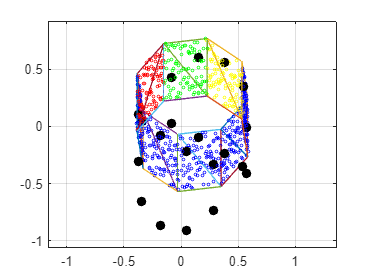

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'red')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end

scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')

## 构建复测数据

% 构建测点输入
PointIn = [];
for i = 1:shenglunum
    temp = [PointTable_A_off8(:,i),PointTable_A_off8(:,end+1-i)];
    PointIn = [PointIn,temp];
end

% 计算参数（用于输入）
[PlaneParaOut,TrianglePoints4,~,~] = planefit4(side_faces_transformed1',side_faces_transformed3',side_faces_transformed5',side_faces_transformed7',P_bound1,P_bound2,distanceThreshold);
[Pin,Pout,UPP,b,h,~,Tao,~] = Calculate_rectangle_from_vertex(TrianglePoints4);




## 计算距离

[Distance,theta,LTPY,TiC,Wquanzhong3,Wquanzhong4]=JuXingFuCe(PointIn,shenglunum,Pin,Tao,h,PlaneParaOut)

Distance =     0.9413    1.6173    1.8291    1.6185    0.9456


theta =     0.5283    0.5283    0.5283    0.5283    0.5283


LTPY =    -0.8895   -0.2131   -0.0009   -0.2110   -0.8836


TiC =    -0.8942   -0.8969   -0.5255   -0.5302    0.0026    0.0026    0.5302    0.5255    0.8970    0.8942


Wquanzhong3 =     0.2580
    0.2580
    0.4596
    0.4596
    0.5661
    0.5661
    0.4640
    0.4640
    0.2522
    0.2522


Wquanzhong4 =     0.2456
    0.2456
    0.4711
    0.4711
    0.5562
    0.5562
    0.4751
    0.4751
    0.2403
    0.2403
